clear; %Limpio Espacio de trabajo
clc;

narm=200; %Numero de armonicos tomados para reconstruir la señal

A=1; %Amplitud rampa

Tr=4; %Periodo rampa
To=3; %Periodo ceros
T=Tr+To; %Periodo de la señal

f=1/T; %Frecuencia
fs=(1/T):1/T:(narm/T); %Normalizacion vector de Frecuencia

np=T*0.01; %Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
t=-(2*T):np:(2*T); %Limites del espacio numerico (eje de abscisas ¨tiempo¨)


dds = tripuls(t,0.2,-1); %Funcion de referencia ¨Diente de sierra original¨
tpul = 0;%pulstran(t,d,x,f);

%---------------------------CALCULO DE COEFICIENTES--------------------------
%---------------------------Bn--------------------------
syms x n;
dib=(x/Tr+1/8)*sin(2*pi*n*f*x); %Expresion dentro de la integral b 'dib'
bn=(2/T)*int(dib,[-1/2 7/2]); %Integral definida en el periodo de la rampa
bn=simplify(bn)

$$bn = \frac{7\,\sin\left(\frac{\pi \,n}{2}\right)+7\,\sin\left(\frac{\pi \,n}{14}\right)-4\,\pi \,n\,\cos\left(\frac{\pi \,n}{2}\right)}{4\,n^{2}\,\pi^{2}}$$

%---------------------------An--------------------------
syms x n;
dia=(x/Tr+1/8)*cos(2*pi*n*f*x); %Expresion dentro de la integral a 'dia'
an=(2/T)*int(dia,[-1/2 7/2]);
an=simplify(an)

$$an = \frac{7\,\cos\left(\frac{\pi \,n}{2}\right)-7\,\cos\left(\frac{\pi \,n}{14}\right)+4\,\pi \,n\,\sin\left(\frac{\pi \,n}{2}\right)}{4\,n^{2}\,\pi^{2}}$$

%---------------------------Ao--------------------------
syms x n;
diao=(x/Tr+1/8); %Expresion dentro de la integral a 'diao'
ao=(1/T)*int(diao,[-1/2 7/2])

$$ao = \frac{1}{7}$$

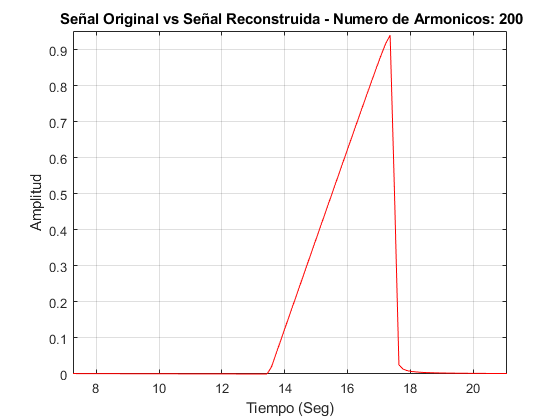

ao=double(ao);
%-----------------------------------------------------------------------------

%--------------------Ciclo sumatoria coeficientes---------------------------
Sefu=ao;% Inicializo con el nivel DC
for n=1:narm %Ciclo de sumatoria (desde n=1 hasta el numero de armonicos deseados (narm))
    anf=subs(an);%Evaluo el coeficiente a en n
    anf=double(anf);%Convierto el coeficiente en numero para optimizar calculos
    Sefua=anf*cos(2*pi*n*f*t);
    bnf=subs(bn);
    bnf=double(bnf);
    Sefub=bnf*sin(2*pi*n*f*t);
    mag(n)=sqrt(bnf^2+anf^2);%Vector del espectro de magnitud
    Sefu=Sefu+(Sefua+Sefub);
end
%-----------------------------------------------------------------------------


%--------------------Graficacion de Resultados---------------------------
plot(t,tpul,'b',t,Sefu,'r'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud; %Graficacion de Resultados
title(['\bf Señal Original vs Señal Reconstruida - Numero de Armonicos: ',num2str(n),'']);

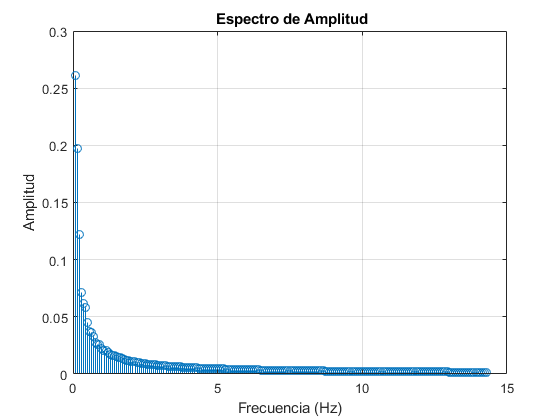

stem(fs,mag),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud; %Graficacion de Resultados
title('\bf Espectro de Amplitud');

%-----------------------------------------------------------------------------